
bpm_to_hertz = 1/60;

% 160 bpm to hertz
known_bpm = 160;

known_bpm * bpm_to_hertz

ans = 2.6667


% 100 readings per second
raw_data_160 = readtable('160_bpm.csv');
size(raw_data_160)

ans =         1834           5


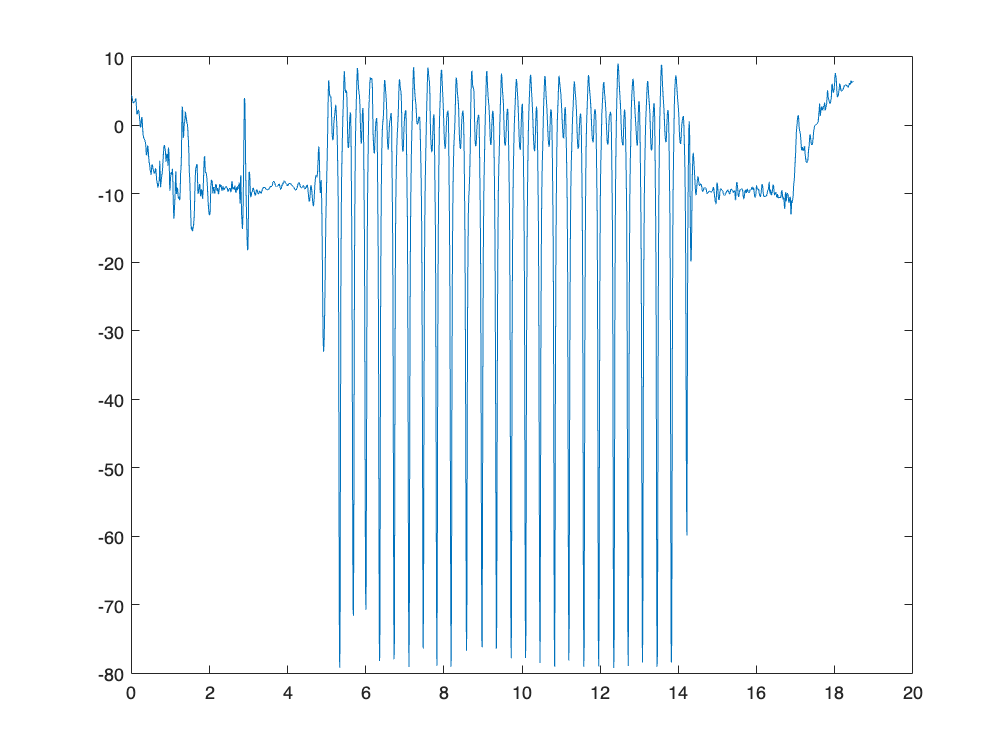

plot(raw_data_160.t, raw_data_160.a_y)

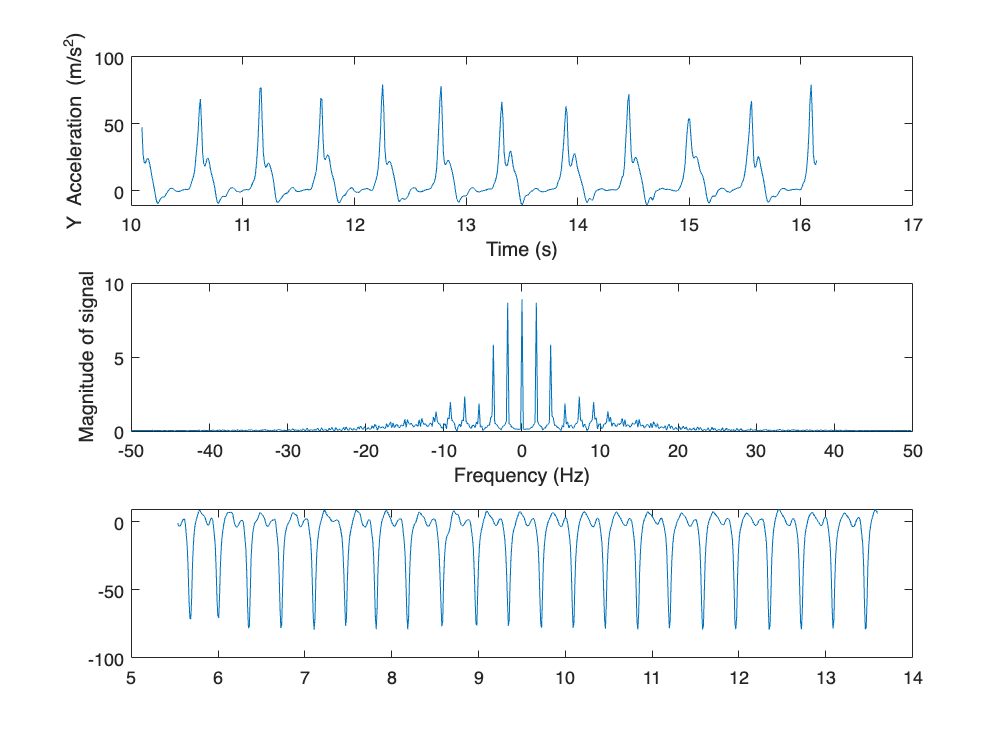

% trim data to time range
time_range = 550:1350;
t_trim = raw_data_160.t(time_range);
a_y_trim = raw_data_160.a_y(time_range);
plot(t_trim, a_y_trim)

% sample fs is 100 hz
make_freq_plot(a_y_trim, 100)

'make_freq_plot' is not found in the current folder or on the MATLAB path, but exists in:
    /Users/oliviachang/coding/qea-final-project

Change the MATLAB current folder or add its folder to the MATLAB path.

ans = 7.6051

maxMagFreqValue = 2.7500

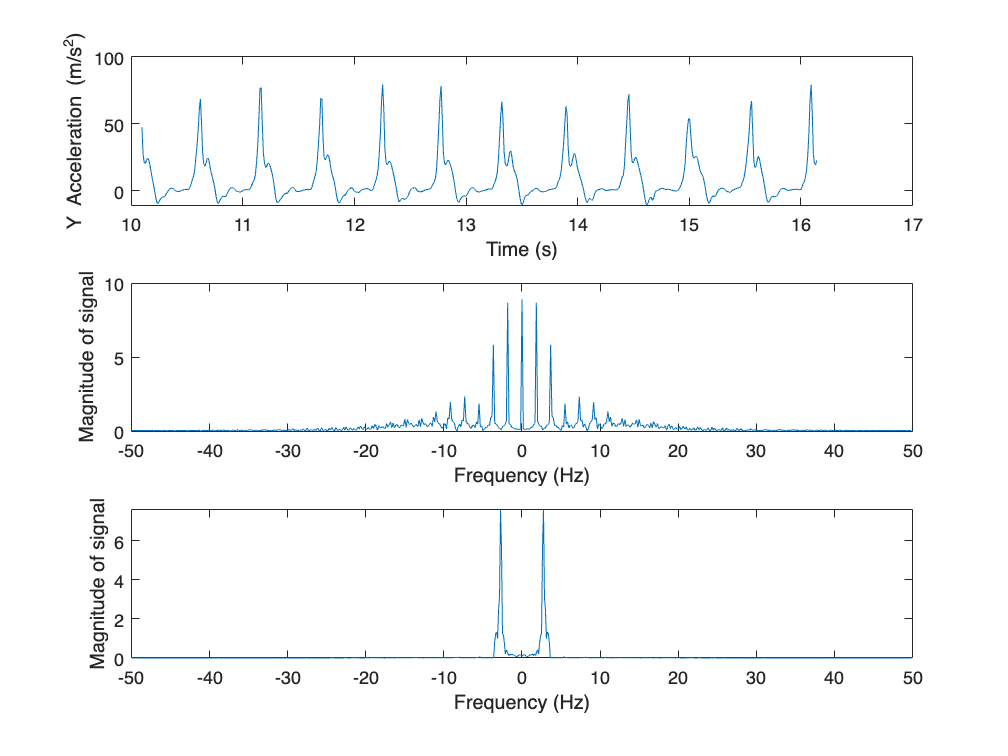

make_freq_plot_suppress(a_y_trim, 100)

% should filter out the frequencies that we aren't looking for
% take dft
dftx = fft(a_y_trim);

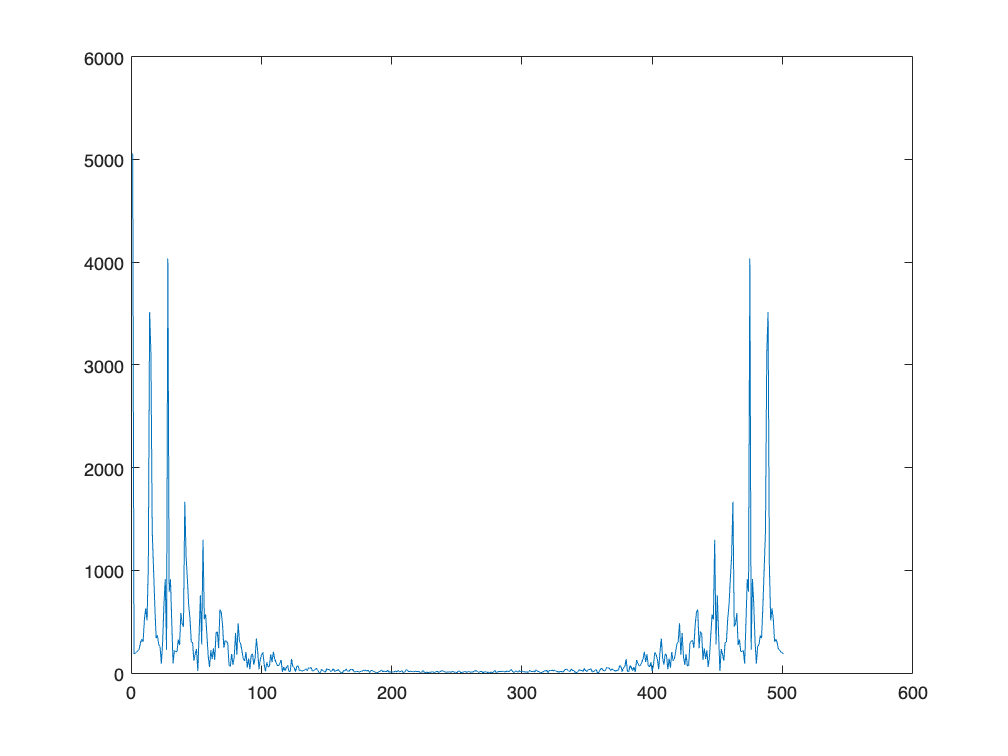

% plot dft
plot(abs(dftx))

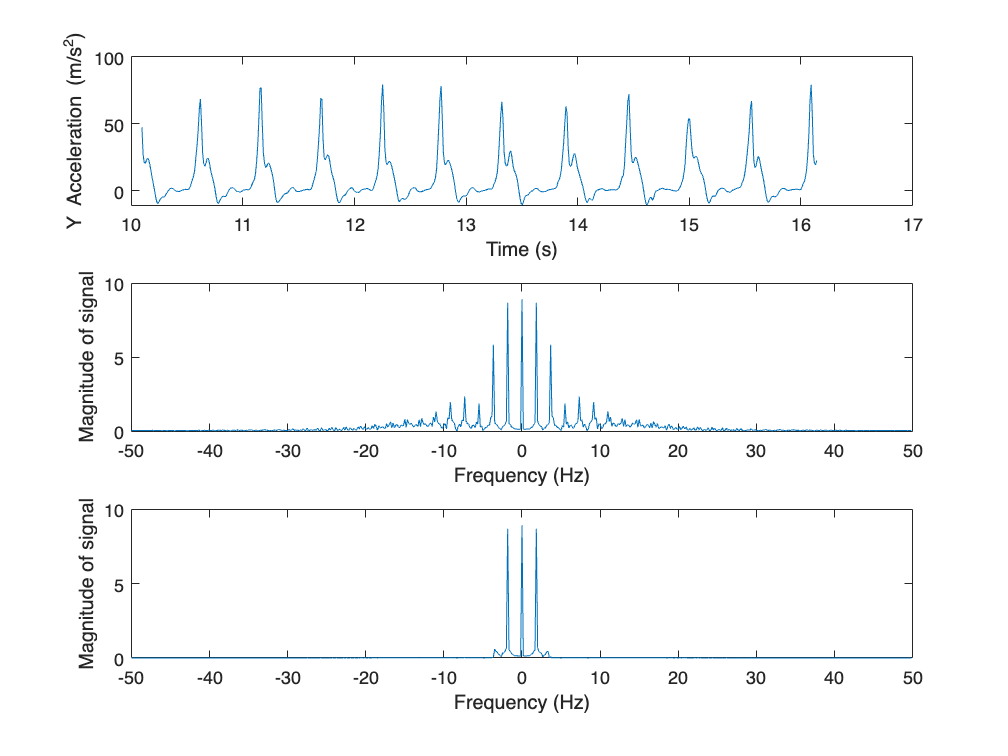

plotData('110_bpm.csv')
processData('110_bpm.csv', 110, 10, 16)

function plotData(csv_filename)
    raw_data = readtable(csv_filename);
    plot(raw_data.t, raw_data.a_y)
end

function processData(csv_filename, known_bpm, t_start, t_end)
    raw_data = readtable(csv_filename);
    t_trimmed = raw_data.t(t_start * 100:t_end * 100);
    a_y_trimmed = raw_data.a_y(t_start * 100:t_end * 100);

    % plot trimmed data
    subplot(3,1,1);
    plot(t_trimmed, a_y_trimmed)
    xlabel("Time (s)")
    ylabel("Y Acceleration (m/s^2)")
    
    % plot frequency graph without suppression
    subplot(3,1,2);
    make_freq_plot(a_y_trimmed, 100)

    % plot frequency graph, suppressed
    subplot(3,1,3);
    make_freq_plot_suppress(a_y_trimmed, 100)
end